p=[1 3 -1]; %manually initialized perceptron
xpos=[1 2 3; 1 3 1]; %training positive inputs, desired output 1
xneg=[3 4 4; 4 2 4]; %training negative inputs, desired output 0
x=[xpos xneg];
perm=[1 4 6 2 3 5];
x=x(:,perm) %permute the training smaples

x =      1     3     4     2     3     4
     1     4     4     3     1     2


c=[ones(1,3) zeros(1,3)];
c=c(perm) %permute also the desired outputs

c =      1     0     0     1     1     0


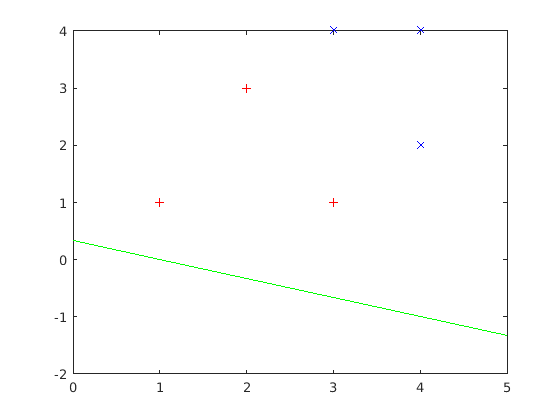

xr=0:5; %plot the samples and the separa

plot(xpos(1,:),xpos(2,:),"+r", ...
    xneg(1,:),xneg(2,:), "xb", ...
    xr,-(p(1)*xr+p(3))/p(2), "g")


%learn the perceptron and depict the result
pn=perc_learn(p,x,c,0.5,100) 

pn =    -3.5000   -0.5000   12.0000


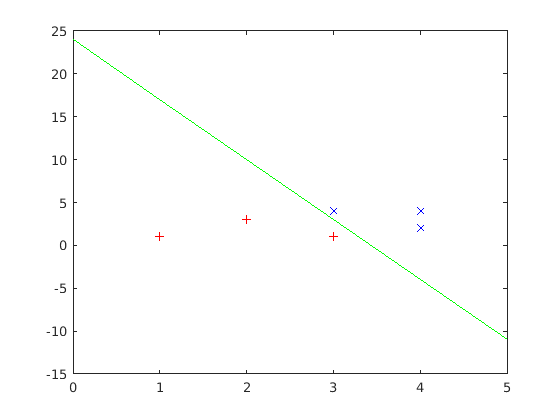


% plot it
plot(xpos(1,:),xpos(2,:),"+r", ...
    xneg(1,:),xneg(2,:), "xb", ...
    xr,-(pn(1)*xr+pn(3))/pn(2),"g")